# ระบบหุ่นยนต์ ROS

Robot Operating System (ROS) is a communication interface that enables different parts of a robot system to discover each other, and send and receive data between them. 

- A *ROS network* comprises different parts of a robot system (such as a planner or a camera interface) that communicate over ROS. The network can be distributed over several machines.

- A *ROS master* coordinates the different parts of a ROS network. It is identified by a *Master URI* (Uniform Resource Identifier) that specifies the hostname or IP address of the machine where the master is running.

- A *ROS node* contains a collection of related ROS capabilities (such as publishers, subscribers, and services). A ROS network can have many ROS nodes.

- *Publishers*, *subscribers*, and *services* are different kinds of ROS entities that process data. They exchange data using *messages*.

- A publisher sends messages to a specific *topic* (such as "odometry"), and subscribers to that topic receive those messages. A single topic can be associated with multiple publishers and subscribers.

ROS Toolbox provides an interface connecting MATLAB® and Simulink® with the Robot Operating System (ROS and ROS 2), enabling you to create a network of ROS nodes. The toolbox includes MATLAB functions and Simulink blocks to import, analyze, and play back ROS data recorded in rosbag files. You can also connect to a live ROS network to access ROS messages.

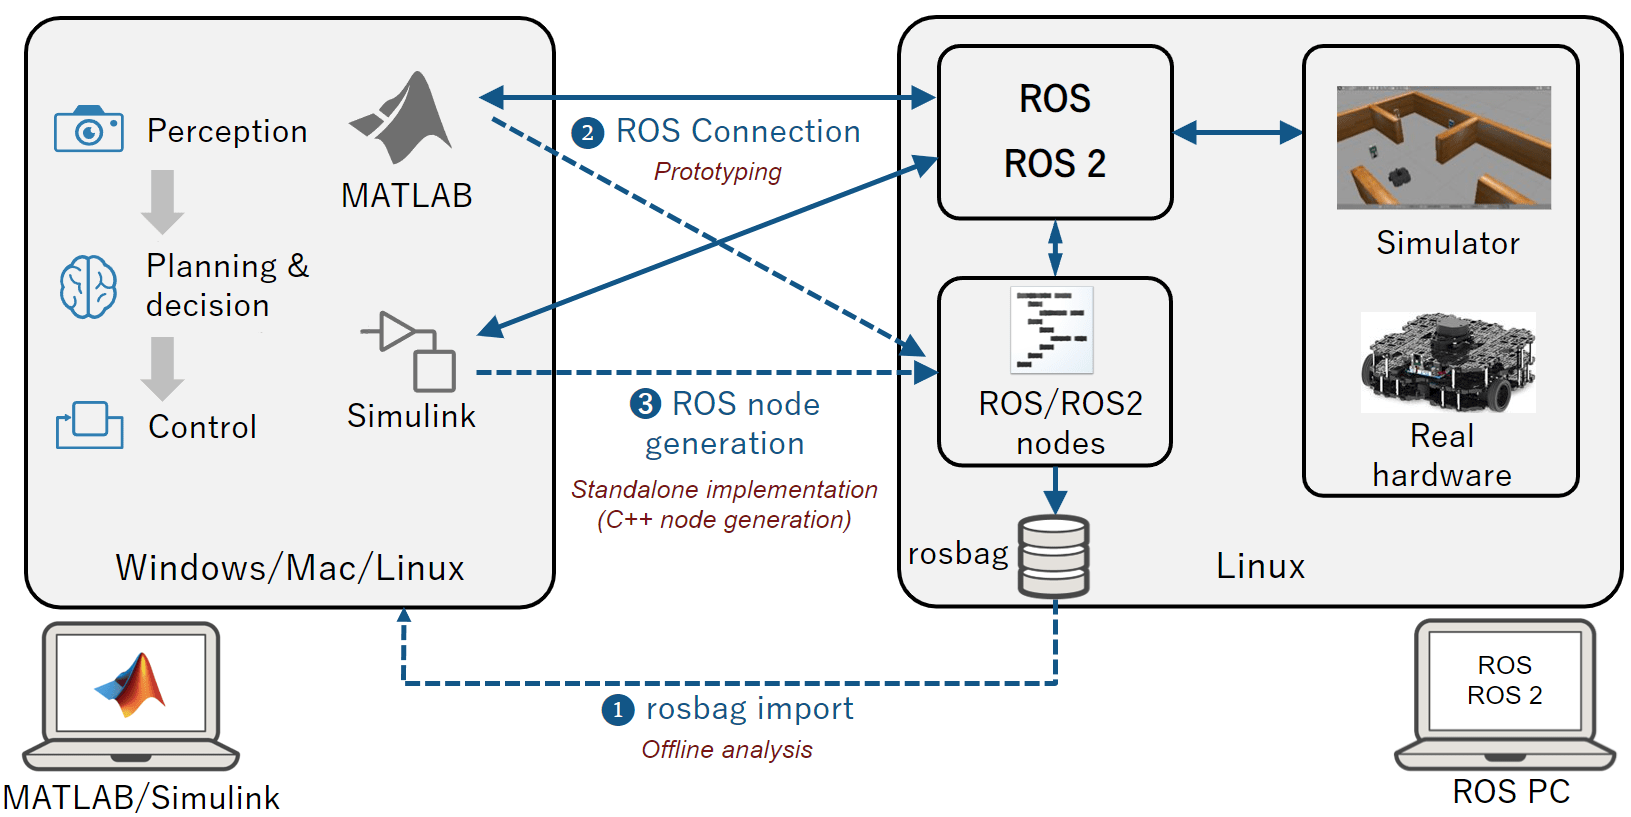

#### อ้างอิง

[Get Started with ROS - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/ros/ug/get-started-with-ros.html)

### สาธิตตัวอย่าง

The virtual machine is a supplement to Robotics System Toolbox™ and ROS Toolbox™. You can use MATLAB® and Simulink® to work with the [Gazebo](https://gazebosim.org/) robot simulator and an external [ROS](http://www.ros.org/) (Robot Operating System) and [ROS 2](https://index.ros.org/doc/ros2/) network. Ubuntu® Bionic 20.04 virtual machine works on multiple platforms (Windows®, Mac, and Linux®) and contains the following:

- [ROS 2 Foxy](https://docs.ros.org/en/foxy/Releases/Release-Foxy-Fitzroy.html) desktop installation

- [ROS Noetic](http://wiki.ros.org/noetic) desktop installation

- [Gazebo](https://gazebosim.org/) robot simulator 11.0.0

#### Installation Instructions:

- Download and install the [VMware®](https://download3.vmware.com/software/player/file/VMware-player-12.1.1-3770994.exe)[ Player software](https://www.vmware.com/go/getplayer-win) [(license)](https://www.vmware.com/download/eula/universal_eula.html).

- Download the [archive](https://ssd.mathworks.com/supportfiles/ros/virtual_machines/v3/ros_noetic_foxy_gazebov11_linux_win_v1.zip) containing the virtual machine.

- Decompress the archive to a location on your hard drive.

- Start VMware Player. Press **Open a Virtual Machine**.

- Browse to the location of the Ubuntu image, select the ros_noetic_foxy_gazebov11.vmx file and press **OK**.

- In VMware Player, start the virtual machine.

- Press **I copied it** if a window opens that asks if you copied or moved the virtual machine.

#### VMWare network configuration:

- Change VM Network Adaptor to **Bridged**.

- Edit bash script: `sudo nano /home/usr/start-gazebo-pickplace.sh`

- Change command to get IPv4: `export ROS_IP=$(hostname -I | cut -f1 -d ' ')`

- Type Ctrl+x to save.

#### อ้างอิง

[ROS 2 Dashing and Gazebo - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/support/product/robotics/ros2-vm-installation-instructions-v6.html)

`rosinit` starts the global ROS node with a default MATLAB® name and tries to connect to a ROS master running on `localhost` and port `11311`. If the global ROS node cannot connect to the ROS master, `rosinit` also starts a ROS core in MATLAB, which consists of a ROS master, a ROS parameter server, and a rosout logging node.

The first time you connect to a ROS network, you must install and setup [Python](https://www.python.org/downloads/).

- From R2020b to R2021b, install Python® 2.7.

- From R2022a or later, install Python 3.9.

openExample('robotics/PickandPlaceWorkflowInGazeboUsingROSExample')

liveNode =   ros2node with properties:

    Name: '/liveNode'
      ID: 0


chatPub =   ros2publisher with properties:

      TopicName: '/talk'
    MessageType: 'std_msgs/String'
        History: 'keeplast'
          Depth: 10
    Reliability: 'reliable'
     Durability: 'volatile'


/liveNode


### ขั้นที่ 1 เชื่อมต่อ ROS network

Robot Operating System 2 (ROS 2) is the second version of ROS, which is a communication interface that enables different parts of a robot system to discover, send, and receive data. MATLAB® support for ROS 2 is a library of functions that allows you to exchange data with ROS 2 enabled physical robots or robot simulators such as Gazebo®. ROS 2 is built on Data Distribution Standard (DDS) which is an end-to-end middleware that provides features such as discovery*, *serialization and transportation. These features align with the design principles of ROS 2 such as* distributed discovery* and control over different *"Quality of Service"* options for transportation. DDS uses Real Time Publish-Subscribe (RTPS) protocol which provides communication over unreliable network protocols such as UDP.

**ROS 2 Terminology**

- A *ROS 2 network* comprises different parts of a robot system (such as a planner or a camera interface) that communicate over ROS 2 network. The network can be distributed over several machines.

- A *ROS 2 node* is an entity that contains a collection of related ROS 2 capabilities (such as publishers and subscribers). A ROS 2 network can have many ROS 2 nodes.

- *Publishers* and *subscribers* are different kinds of ROS 2 entities that process data. They exchange data using *messages*.

- A publisher sends messages to a specific *topic* (such as "odometry"), and subscribers to that topic receive those messages. There can be multiple publishers and subscribers associated with a single topic.

- A *Domain* is the physical segmentation of network. It is identified by a unique integer value known as *Domain ID.* By default the *Domain ID* is `0`.

- Every node in ROS 2 network on creation advertises its presence to other nodes in the same *Domain ID* only*.*

- *ROS 2* network is built on Data Distribution Standard (DDS) which makes it possible to connect multiple nodes across distributed network.

- *RTPS* (Real Time publisher-subscriber) protocol provides ROS 2 network with capabilities to send messages in unreliable network conditions.

- ROS 2 offers variety of *Quality of Service (QoS)* policies that allow you to tune your communication between nodes. For more information, see [Manage Quality of Service Policies in ROS 2](https://www.mathworks.com/help/ros/ug/manage-quality-of-service-policies-in-ros2.html).

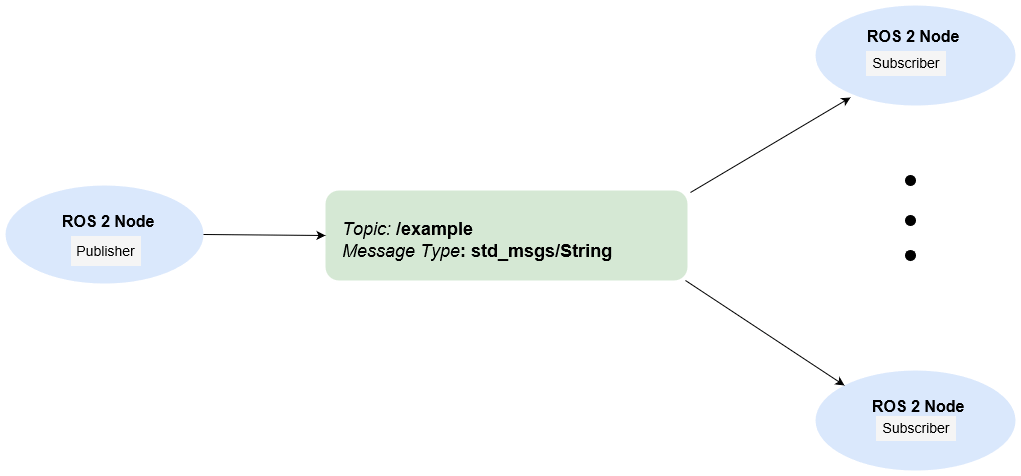

The primary mechanism for ROS 2 nodes to exchange data is to send and receive *messages*. Messages are transmitted on a *topic* and each topic has a unique name in the ROS 2 network. If a node wants to share information, it must use a *publisher* to send data to a topic. A node that wants to receive that information must use a *subscriber* for that same topic. Besides its unique name, each topic also has a *message type*, which determines the type of messages that are allowed to be transmitted in the specific topic.

This publisher-subscriber communication has the following characteristics:

- Topics are used for many-to-many communication. Multiple publishers can send messages to the same topic and multiple subscribers can receive them.

- Publisher and subscribers are decoupled through topics and can be created and destroyed in any order. A message can be published to a topic even if there are no active subscribers.

#### อ้างอิง

[Get Started with ROS 2 - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/ros/ug/get-started-with-ros-2.html)

[Exchange Data with ROS 2 Publishers and Subscribers - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/ros/ug/exchange-data-with-ros-2-publishers-and-subscribers.html)

liveNode = ros2node("/liveNode")
chatPub = ros2publisher(liveNode,"/talk","std_msgs/String")
ros2 node list

msg = ros2message(chatPub);
msg.data = 'Hello';
send(chatPub, msg);